# **RS-WISP-06-01: Two Impulse Rendezvous Visualization**

**WorkerInSpace**

**Hongseok Kim**

**2/12/2025**

addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions')

## I. Satellite Orbit Initialization

### I.1 Add Epoch Information

%% Input Parameters

%Initial Epoch Definition
Year = 2025;
Month = 3;
Day = 21;
Hour = 1;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = seconds(28800);
steptime = 15;


startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
stopTime = startTime + duration;
scenario = satelliteScenario(startTime,stopTime,steptime);

time_vector = scenario.StartTime:seconds(scenario.SampleTime):scenario.StopTime;

### I.2 Run Two-Impluse Rendezvous Function

% Target Information
Target.a = 300+6378;
Target.e = 1e-5;
Target.i = 40;
Target.RAAN = 20;
Target.AOP = 0;
Target.TA = 60;


% Chaser Information
Chaser.a = 6378 + (318.5 + 515.51)/2;
Chaser.e = (6378+515.51)/Chaser.a-1;
Chaser.i = 40.130;
Chaser.RAAN = 19.819;
Chaser.AOP = 70.662;
Chaser.TA = 349.65;


%% Main Algorithm
% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

% Timing of Docking
t_f = seconds(duration);
[Delta_v_0, Delta_v_f, delta_r_t_mat, delta_v_t, v_plus_ECI, t_vector] = two_impulse_rendezvous(r_target, v_target, r_chaser, v_chaser, t_f);


% Change to rv values
[Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA] = ijk2kepler_hs(r_chaser, v_plus_ECI);


### I.3 Initialize Visualization

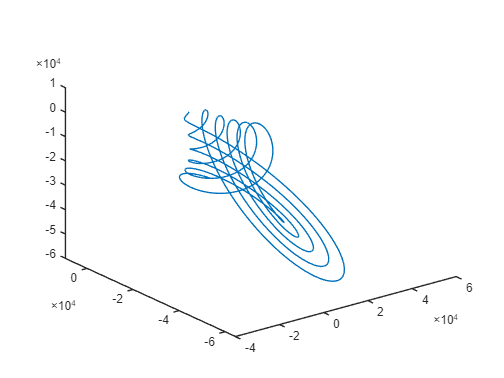

Orbit_propagator = 'SGP4';
sat_name = 'target';

target_satellite = satellite(scenario,Target.a*1000, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA, ... 
                             Name = sat_name, ...
                             OrbitPropagator = Orbit_propagator);


sat_name = 'chaser';
chaser_satellite = satellite(scenario,Chaser.a*1000, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA, ... 
                             Name = sat_name, ...
                             OrbitPropagator  = Orbit_propagator);


satellites_location_information = states(scenario.Satellites);
target_location_info =  satellites_location_information(:,:,1)';
chaser_location_info = satellites_location_information(:,:,2)';

relative_distance = target_location_info - chaser_location_info;
relative_distance_norm = zeros(length(time_vector),1);


for i = 1:length(time_vector)
    relative_distance_norm(i) = norm(relative_distance(i,:));
end

plot3(relative_distance(:,1),relative_distance(:,2),relative_distance(:,3))

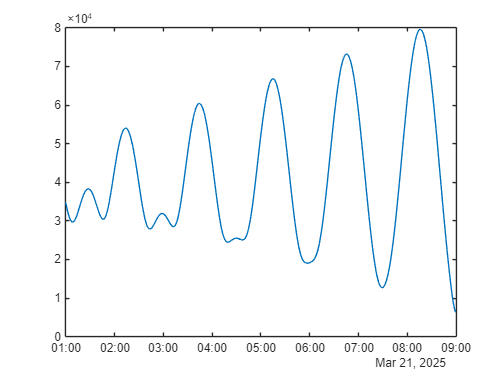


plot(time_vector,relative_distance_norm)




play(scenario)